# Control Hinf

Controlador que minimice el peor efecto de una perturbación, en cualquier frecuencia.

Antes de partir que tenemos, 

- Masa del brazo: $m=0\ldotp 080\textrm{kg}$ (80 Gramos)

- Gravedad: $g=9\ldotp 81\;m/s^2$

- Pivote a Centro de Masa: $d=0\ldotp 05\;m\;\left(5\textrm{cm}\right)$ 

- Momento de Inercia: $J=4\ldotp 2860\times {10}^{-4} \;\textrm{kg}\cdot m^2$

- Fricción Viscosa: $b=8\ldotp 3032\times {10}^{-4} \;N\cdot m\cdot s/\textrm{rad}$

- Constante del Actuador/Hélice: $K=1\ldotp 0492\times 10-3N\cdot m/%\textrm{PWM}$

- Punto de Operación: $\theta_0 =70\degree \Longrightarrow \textrm{cos }\left(70\degree \right)\approx 0\ldotp 3420$

Ecuación diferencial linealizada alrededor de 70°


$$J\ddot{\theta} \left(t\right)+b\dot{\theta} \left(t\right)+m*g*d*\cos \left(\theta_0 \right)\theta \left(t\right)=\textrm{Ku}\left(t\right)$$
 

Aplicamos transformada de laplace para halla la TF


$$G\left(s\right)=\frac{B_0 }{s^2 +A_1 s+A_0 }$$


Donde 


$$G\left(s\right)=\frac{\frac{K}{J}}{s^2 +\frac{b}{J}s+\frac{m\;g\;d\;\cos \theta_0 }{J}}$$



$$A_1 =\frac{b}{J}=\frac{8\ldotp 3032\times {10}^{-4} }{4\ldotp 2860\times {10}^{-4\;\;} }=1\ldotp 937s^{-1}$$



$$A_0 =\frac{m*g*d*\cos \left(\theta_0 \right)}{J}=31\ldotp 32{\textrm{rad}}^2 /s^2$$



$$B_0 =\frac{K}{J}*\left(\frac{180}{\pi }\right)=140\ldotp 3\;\frac{\textrm{grados}}{\left(s^2 \cdot %\textrm{PWM}\right)}$$
 


$$G\left(s\right)=\frac{140\ldotp 3}{s^2 +1\ldotp 937s+31\ldotp 32}$$


% =========================================================================
% ANÁLISIS DE LA PLANTA Y CONTROLADOR PID DEL INFORME EN MATLAB
% =========================================================================
clc; clear; close all;

%% 1. DEFINICIÓN DE LA PLANTA G(s) (Grados / %PWM)
% G(s) = 140.3 / (s^2 + 1.937*s + 31.32)
num_G = [140.3];
den_G = [1, 1.937, 31.32];
G = tf(num_G, den_G);

disp('--- Función de Transferencia de la Planta G(s) ---');

--- Función de Transferencia de la Planta G(s) ---


G


G =
 
          140.3
  ---------------------
  s^2 + 1.937 s + 31.32
 
Continuous-time transfer function.



%% 2. DEFINICIÓN DEL CONTROLADOR PID C(s)
% Ganancias del informe: Kp = 0.28, Ki = 1.0, Kd = 0.20, N = 100
Kp = 0.28; 
Ki = 1.0; 
Kd = 0.20; 
N = 100;

s = tf('s');
C = Kp + Ki/s + (Kd*N*s)/(s + N);

disp('--- Función de Transferencia del Controlador PID C(s) ---');

--- Función de Transferencia del Controlador PID C(s) ---


C = minreal(C)


C =
 
  20.28 s^2 + 29 s + 100
  ----------------------
       s^2 + 100 s
 
Continuous-time transfer function.



%% 3. LAZO ABIERTO L(s) Y MÁRGENES DE ESTABILIDAD
L = C * G;

% Graficar el diagrama de Bode de Lazo Abierto con márgenes de Fase y Ganancia
figure('Name', 'Diagrama de Bode de Lazo Abierto L(s)');
margin(L);
grid on;

%% 4. LAZO CERRADO T(s) (Respuesta del sistema)
T = feedback(L, 1);

% Graficar la respuesta al escalón en lazo cerrado
figure('Name', 'Respuesta al Escalón en Lazo Cerrado');
step(T);
title('Respuesta Temporal del Ángulo \theta(t) a un Escalón de Referencia');
ylabel('Ángulo [grados]');
xlabel('Tiempo [segundos]');
grid on;

H infinito 

% =========================================================================
% SÍNTESIS, ANÁLISIS COMPLETO Y DISCRETIZACIÓN DE CONTROL H-INFINITO (AEROPÉNDULO)
% =========================================================================
clc; clear; close all;

%% 1. PARÁMETROS FÍSICOS Y PLANTA G(s) (Grados / %PWM)
m = 0.080;       % kg   masa equivalente del brazo
g = 9.81;        % m/s2 gravedad
d = 0.05;        % m    distancia del pivote al CM
J = 4.2860e-4;   % kg*m2 momento de inercia
b = 8.3032e-4;   % N*m*s/rad coeficiente de friccion
K = 1.0492e-3;   % N*m/%PWM ganancia de la helice
theta0 = deg2rad(70.0); % Punto de operacion

% Coeficientes linealizados
A1 = b / J;                         % 1.937
A0 = (m * g * d * cos(theta0)) / J; % 31.32
B0 = (K / J) * (180 / pi);          % 140.3 (ganancia en grados/%PWM)

% Planta continua G(s)
G = tf([B0], [1, A1, A0]);

%% 2. SÍNTESIS H-INFINITO EN TIEMPO CONTINUO (Sensibilidad Mixta)
M  = 1.5;   % Pico maximo de sensibilidad (6 dB)
wb = 5.6;   % Ancho de banda (wn = 5.6 rad/s)
A  = 1e-4;  % Cota de error estado estable (~0)

W1 = tf([1/M, wb], [1, wb*A]);     % Peso de desempeño (Error S)
W2 = 0.0005;                       % Peso de esfuerzo de control (Actuador KS)
wt = 100.0;
W3 = tf([1, wt/M], [M, wt]);       % Peso de robustez (Ruido T)

% Sintesis por sensibilidad mixta
[C_hinf, CL, gamma] = mixsyn(G, W1, W2, W3);
C_hinf = minreal(C_hinf); % Limpieza de polos/ceros redundantes

1 state removed.



%% 3. DISCRETIZACIÓN POR EL MÉTODO TUSTIN (BILINEAL)
Ts = 0.01; % Tiempo de muestreo: 10 ms (Frecuencia de muestreo: 100 Hz)
C_z = c2d(C_hinf, Ts, 'tustin');

% Extraer coeficientes para el filtro en diferencias de Arduino
[num_z, den_z] = tfdata(C_z, 'v');
b0 = num_z(1); b1 = num_z(2); b2 = num_z(3);
a1 = den_z(2); a2 = den_z(3);

%% 4. CÁLCULO DE MÉTRICAS DE CALIDAD Y ROBUSTEZ
L = C_hinf * G;          % Lazo abierto continuo
S = feedback(1, L);      % Funcion de Sensibilidad
T = feedback(L, 1);      % Funcion de Sensibilidad Complementaria

% Obtener margenes de estabilidad de forma compatible con cualquier version
[GM_lineal, PM_deg, wpc, wc_cruce] = margin(L);
GM_dB = 20*log10(GM_lineal);

% Medir normas H-infinito reales (pico de ganancia en frecuencia)
peak_S = norm(S, inf);
peak_T = norm(T, inf);

% Mostrar metricas en ventana de comando
fprintf('\n================== MÉTRICAS DE CALIDAD DEL DISEÑO ==================\n');


================== MÉTRICAS DE CALIDAD DEL DISEÑO ==================


fprintf('Valor de Gamma alcanzado:   %8.4f  (Debe ser <= 1 para exito)\n', gamma);

Valor de Gamma alcanzado:     0.6912  (Debe ser <= 1 para exito)


fprintf('Margen de Fase (PM):        %8.2f grados a %4.2f rad/s\n', PM_deg, wc_cruce);

Margen de Fase (PM):           88.15 grados a 30.64 rad/s


fprintf('Margen de Ganancia (GM):    %8.2f dB a %4.2f rad/s\n', GM_dB, wpc);

Margen de Ganancia (GM):       39.22 dB a 1631.42 rad/s


fprintf('Pico de Sensibilidad ||S||: %8.4f  (Diseñado para <= M = 1.500)\n', peak_S);

Pico de Sensibilidad ||S||:   1.0290  (Diseñado para <= M = 1.500)


fprintf('Pico de Robustez ||T||:     %8.4f  (Diseñado para <= Mt = 1.500)\n', peak_T);

Pico de Robustez ||T||:       1.0000  (Diseñado para <= Mt = 1.500)


fprintf('Ancho de Banda de Lazo:     %8.2f rad/s\n', bandwidth(T));

Ancho de Banda de Lazo:        31.61 rad/s


fprintf('===================================================================\n');


fprintf('\n================ COEFICIENTES PARA ARDUINO ================\n');


================ COEFICIENTES PARA ARDUINO ================


fprintf('b0 = %12.8f;\n', b0);

b0 =  36.03037033;


fprintf('b1 = %12.8f;\n', b1);

b1 = -35.22793764;


fprintf('b2 = %12.8f;\n', b2);

b2 = -35.91871637;


fprintf('a1 = %12.8f;\n', a1);

a1 =   0.60726418;


fprintf('a2 = %12.8f;\n', a2);

a2 =  -0.95094281;


fprintf('===========================================================\n');

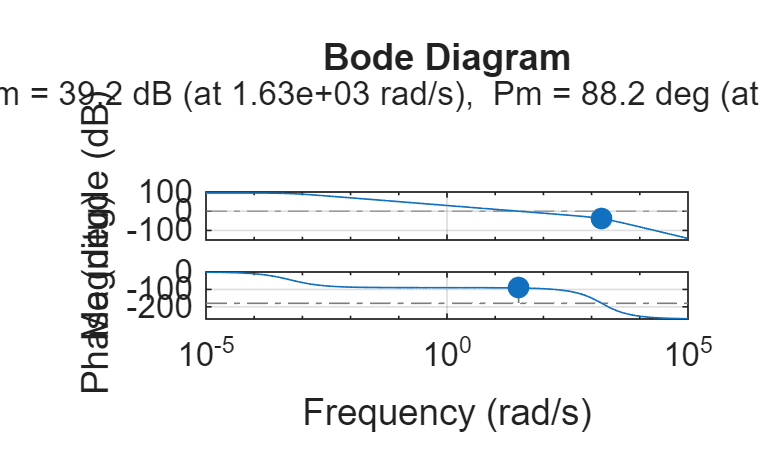


%% 5. GRAFICACIÓN DE RESULTADOS

% Figura 1: Margenes de Lazo Abierto (Bode)
figure('Name', 'Diagrama de Bode de Lazo Abierto (Márgenes de Estabilidad)');
margin(L);
grid on;

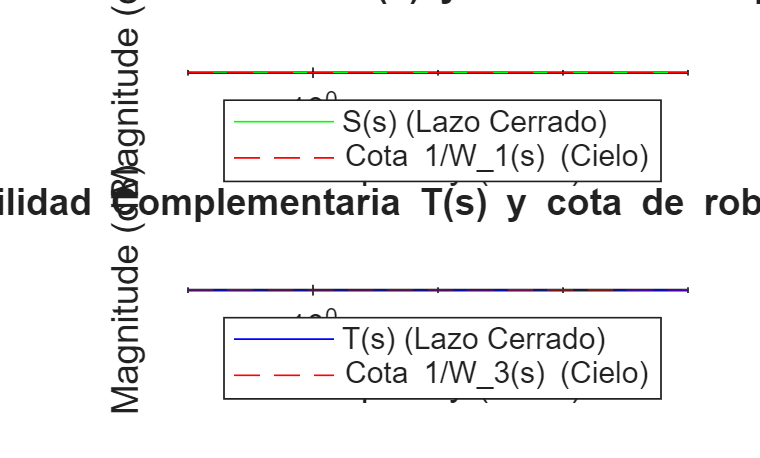


% Figura 2: Comprobación de Techos H-infinito (Frecuencia)
figure('Name', 'Comprobación de Cotas y Ponderaciones H-infinito');
subplot(2,1,1);
bodemag(S, 'g', 1/W1, 'r--', logspace(-1, 3, 1000));
title('Función de Sensibilidad S(s) y cota de desempeño 1/W_1(s)');
legend('S(s) (Lazo Cerrado)', 'Cota 1/W_1(s) (Cielo)');
grid on;

subplot(2,1,2);
bodemag(T, 'b', 1/W3, 'r--', logspace(-1, 3, 1000));
title('Sensibilidad Complementaria T(s) y cota de robustez 1/W_3(s)');
legend('T(s) (Lazo Cerrado)', 'Cota 1/W_3(s) (Cielo)');
grid on;

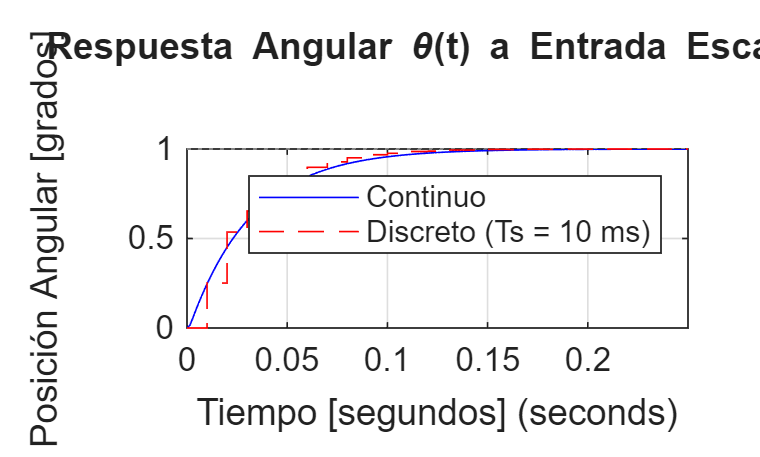


% Figura 3: Respuesta Temporal (Escalón)
T_d = feedback(C_z*c2d(G, Ts, 'zoh'), 1);
figure('Name', 'Respuesta Temporal al Escalón');
step(T, 'b-', T_d, 'r--');
title('Respuesta Angular \theta(t) a Entrada Escalón');
ylabel('Posición Angular [grados]');
xlabel('Tiempo [segundos]');
legend('Continuo', 'Discreto (Ts = 10 ms)');
grid on;

Discretización 


$$u\left\lbrack n\right\rbrack =1\ldotp 53846154u\left\lbrack n-1\right\rbrack -0\ldotp 53846154u\left\lbrack n-2\right\rbrack +27\ldotp 46423077e\left\lbrack n\right\rbrack -53\ldotp 84076923e\left\lbrack n-1\right\rbrack +26\ldotp 38730769e\left\lbrack n-2\right\rbrack$$
